addpath('functions');


i=15;
segment = segmented_tracks{i};
fprintf('Segment %d: %d rows\n', i, height(segment));

Segment 15: 782 rows


disp(segment.BaseDateTime(1:min(3, height(segment))));  % Print first 3 timestamps

   2022-03-31T19:36:25
   2022-03-31T19:36:35
   2022-03-31T19:36:45



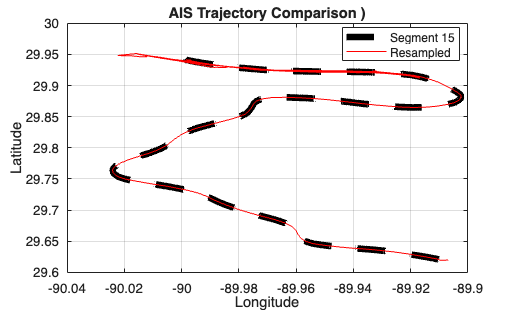

figure;
plot(segment.LON, segment.LAT, 'k--', 'DisplayName', 'Segment 15', 'LineWidth', 5);
hold on;
plot(data_resampled.LON, data_resampled.LAT, 'r-', 'DisplayName', 'Resampled', 'LineWidth', 0.5);
xlabel('Longitude'); ylabel('Latitude');
title(['AIS Trajectory Comparison )']);
legend('Location', 'best'); grid on;

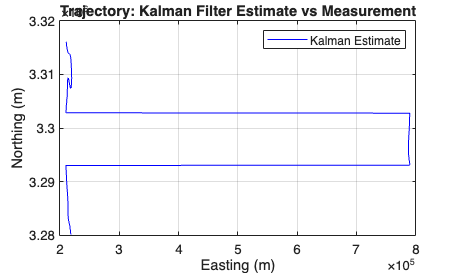

data_segment15 = readtable(fullfile(input_path, ['segment15_ais_', num2str(targetMMSI), '.csv']));
[x_pos, y_pos] = deg2utm(data_segment15.LAT, data_segment15.LON);
figure;
plot(x_pos, y_pos, 'b', 'DisplayName', 'Kalman Estimate');
xlabel('Easting (m)'); ylabel('Northing (m)');
title('Trajectory: Kalman Filter Estimate vs Measurement');
legend('show'); grid on;

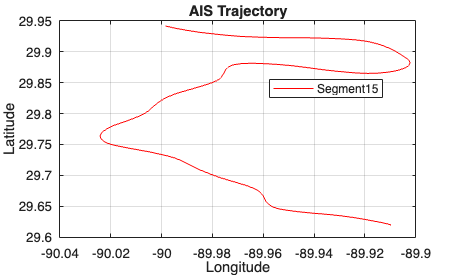

figure;
plot(data_segment15.LON, data_segment15.LAT, 'r-', 'DisplayName', 'Segment15', 'LineWidth', 0.5);
xlabel('Longitude'); ylabel('Latitude');
title(['AIS Trajectory']);
legend('Location', 'best'); grid on;

convertLatLonToUTM('data/segment15_ais_368121820.csv', ...
                          'data/segment15_ais_manualutm.csv');

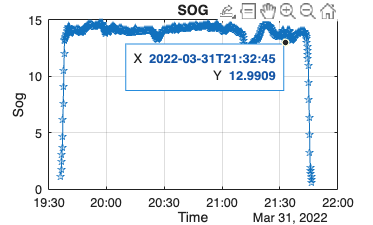

data = readtable(fullfile('data/segment15_ais_manualutm.csv'));
figure;
plot(data.BaseDateTime, data.SOG, 'p-', 'DisplayName', 'SOG');
xlabel('Time');
ylabel('Sog');
title(['SOG']);
grid on;

% Investigate why Position RMSE is always zero in Kalman Filter Evaluation
% Check whether z measurements used in KF match the ground truth or not
% And whether the filter is too confident or data too clean

% Example inspection in evaluateFilter.m or equivalent
% x_est: estimated state [x; vx; y; vy]
% x_gt: ground truth state

% === 1. Visual Check ===
figure;
plot(x_gt(1,:), x_gt(3,:), 'k--', 'DisplayName','Ground Truth');

Unrecognized function or variable 'x_gt'.

hold on;
plot(x_est(1,:), x_est(3,:), 'b', 'DisplayName','KF Estimate');
legend;
title('Trajectory Comparison');

% === 2. RMSE Computation Debug ===
pos_error = x_gt([1 3], :) - x_est([1 3], :);
disp('Max position error in x:'); disp(max(abs(pos_error(1,:))));
disp('Max position error in y:'); disp(max(abs(pos_error(2,:))));

% === 3. Measurement comparison (was z = ground truth?) ===
figure;
plot(x_gt(1,:), 'k--', 'DisplayName','x GT'); hold on;
plot(data.x, 'ro', 'DisplayName','x Measurement');
legend; title('Check if x measurements match GT');

% === 4. Plot RMSE sensitivity to q_pos ===
q_vals = logspace(-2, 2, 20);
rmse_vals = zeros(size(q_vals));
for i = 1:length(q_vals)
    q = q_vals(i);
    Q = makeCVProcessNoise4D(dt, q, 0.5);
    [kf, ~, ~] = predictCorrectKF4D(kf, dt, Q, [data.x(k); data.y(k)]);
    err = x_gt([1 3], k) - kf.State([1 3]);
    rmse_vals(i) = sqrt(mean(err.^2));
end

figure; semilogx(q_vals, rmse_vals, '-o');
xlabel('q_{pos}'); ylabel('Position RMSE');
title('RMSE vs q_{pos}'); grid on;